# Trabajo Practico 1: Transformada Z

## Ejercicio 1

Encontrar la transformada Z de las siguientes señales discretas e indicar su ROC (Region Of Convergence)

- 
$$x[n] = \left[ \frac{1}{3} \right]^n u[n]$$


- 
$$x[n] = -\left[ \frac{1}{2} \right]^n u[-n-1]$$


- 
$$x[n] = \left[ \frac{1}{2} \right]^n u[n] - [2]^n u[-n-1]$$


- 
$$x[n] = -\left[ \frac{1}{2} \right]^n u[n] -\left[ \frac{1}{2} \right]^n u[-n-1]$$


#### 1)


$$\begin{array}{cl}
X(z) & = \sum_{n=-\infty}^{\infty} x[n]z^{-n} \\
& = \sum_{n=-\infty}^{\infty} \left[ \frac{1}{3} \right]^{n} u[n] z^{-n} \\
& = \sum_{n=0}^{\infty} \left( \frac{1}{3}z^{-1} \right)^{n} \\
& = \frac{1}{1-\frac{1}{3}z^{-1}}, \quad |z| > \frac{1}{3}
\end{array}$$


Esta es una señal **causal**.

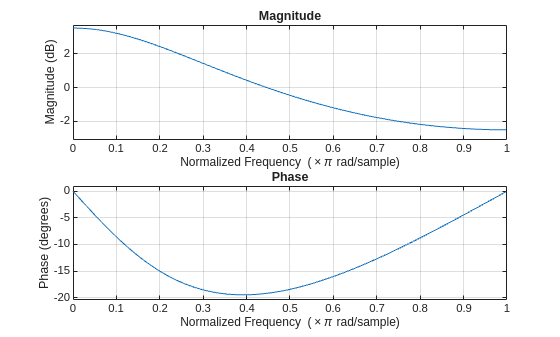

syms n z
x_1 = (1/3)^n;
X1 = ztrans(x_1, n, z);           % 1. Transformada simbólica
[num, den] = numden(X1);          % 2. Separar numerador y denominador
b = sym2poly(num);                % 3. Convertir a vectores numéricos
a = sym2poly(den);
sys = tf(b, a, -1);               % 4. Crear objeto de sistema
freqz(b,a);

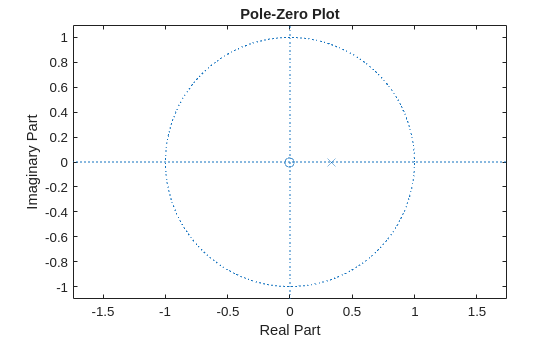

zplane(b, a);                    % 5. Analizar estabilidad

#### 2)


$$\begin{array}{cl}
Z\{ x[n] \}  & = \sum_{n=-\infty}^{\infty} x[n]z^{-n} \\
 & = \sum_{n=-\infty}^{\infty} -\left[ \frac{1}{2} \right]^{n} u[-n-1]  z^{-n} \\
 & = \sum_{n=-\infty}^{-1} -\left[ \frac{1}{2} \right]^{n} z^{-n}  \\
 & = \sum_{n=-\infty}^{-1} -\left( 2z \right)^{-n}  \\
 & = \sum_{n=1}^{\infty} -\left( 2z \right)^{n}  \\
 & = -\frac{2z}{1-2z} \\
 & = \frac{1}{1-\frac{1}{2}z^{-1}} \; , \qquad |z|<| \frac{1}{2} |
\end{array}$$


Esta es una señal **anti-causal**.

syms n z
x_2 = (1/2)^n;
assume(abs(z) < 0.5);
X2 = symsum(x_2 * z^(-n), n, -inf, -1);
X2 = simplify(X2)

$$X2 = -\frac{2\,z}{2\,z-1}$$

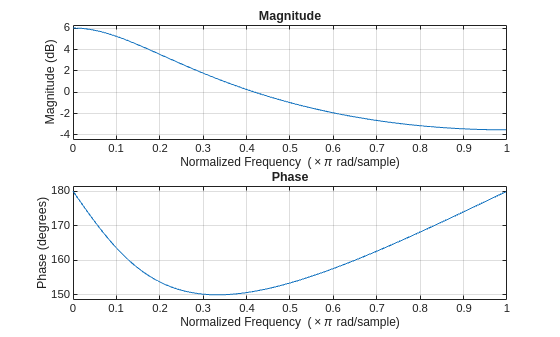

% Multiplicando por (-2z)/(-2z) se llega a la misma exprecion que arriba
b = [-1 0];
a = [1 -0.5];

sys = tf(b, a, -1);               % 4. Crear objeto de sistema
freqz(b,a);

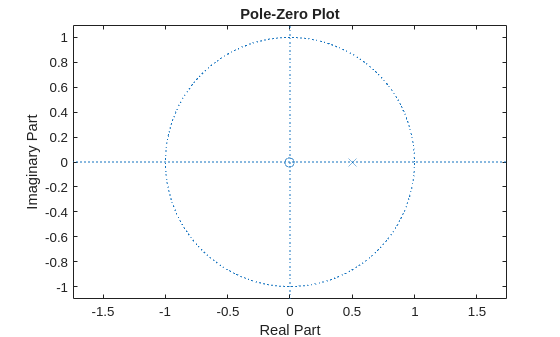

zplane(b,a);

#### 3)


$$\begin{array}{cl}
Z\{ x[n] \}  & = Z \left\{    \left[ \frac{1}{2} \right] ^{n}u[n]-[2]^{n}u[-n-1] \right\}  \\
 & = Z \left\{ \left[ \frac{1}{2} \right] ^{n}u[n] \right\} + Z \Big\{ -[2]^{n}u[-n-1] \Big\}   \\
 & = \frac{1}{1-\frac{1}{2}z^{-1}}+\frac{1}{1-2z^{-1}}  \\
 \\
 & = \frac{\left( 1-\frac{1}{2}z^{-1} \right) + (1-2z^{-1})}{\left( 1-\frac{1}{2}z^{-1} \right) (1-2z^{-1})} \\
 \\
 & = \frac{2-\frac{5}{2}z^{-1}}{1-\frac{5}{2}z^{-1}+z^{-2}}  \; , \qquad \frac{1}{2}  < |z|< 2
\end{array}$$


syms n z
u1 = (1/2)^n; 
U1 = ztrans(u1, n, z)

$$U1 = \frac{z}{z-\frac{1}{2}}$$

u2 = -(2)^n;
assume(abs(z) < 2);                      % Para que devuelva expresion cerrada (comentar para ver caso contrario)
U2 = symsum(u2 * z^(-n), n, -inf, -1)

$$U2 = \frac{z}{z-2}$$

X3 = U1 + U2;
X3 = simplify(X3)

$$X3 = \frac{z}{z-2}+\frac{z}{z-\frac{1}{2}}$$

pretty(X3)

  z       z
----- + -----
z - 2       1
        z - -
            2



% Multiplicando por (-2z)/(-2z) se llega a la misma exprecion que arriba
b = [-1 0];
a = [1 -0.5];

sys = tf(b, a, -1);               % 4. Crear objeto de sistema
freqz(b,a);

zplane(b,a);

#### 4)


$$\begin{array}{cl}
Z\{ x[n] \}  & = Z \left\{ -\left[ \frac{1}{2} \right] ^{n}u[n] \right\} + Z \left\{-\left[ \frac{1}{2} \right]^{n}u[-n-1] \right\}  \\
 & = - \frac{1}{1-\frac{1}{2}z^{-1}} + \frac{1}{1-\frac{1}{2}z^{-1}} \\
 & = 0
\end{array}$$


La señal es **no causal **y** diverge.**

Analizando el ROC de las dos señales por separado:


$$ROC_1: \frac{1}{2}  < |z| \\
ROC_2: \frac{1}{2}  > |z| $$


No existe numero que pueda cumplir ambos requisitos simultaneamente, ergo no existe ROC ($ROC = \emptyset$).

syms n z
u1 = -(1/2)^n; 
U1 = ztrans(u1, n, z)

$$U1 = -\frac{z}{z-\frac{1}{2}}$$

u2 = -(1/2)^n;
assume(abs(z) < 0.5);                      % Para que devuelva expresion cerrada (comentar para ver caso contrario)
U2 = symsum(u2 * z^(-n), n, -inf, -1)

$$U2 = \frac{2\,z}{2\,z-1}$$

X4 = U1 + U2;
X4 = simplify(X3)

$$X4 = 0$$

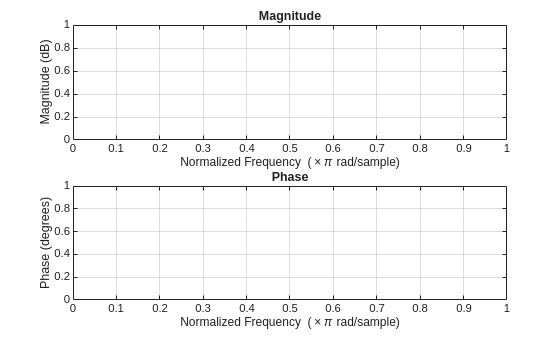

% Multiplicando por (-2z)/(-2z) se llega a la misma exprecion que arriba
b = [0 0];
a = [1];

sys = tf(b, a, -1);               % 4. Crear objeto de sistema
freqz(b,a);

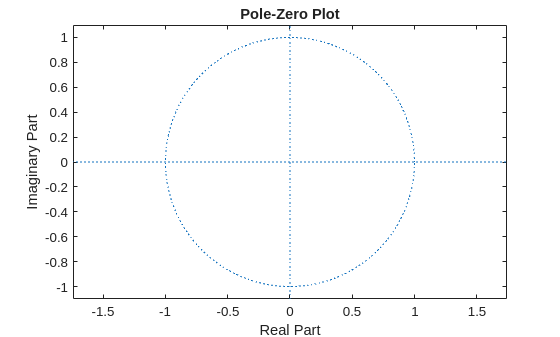

zplane(b,a);

## Ejercicio 2

Considerando las transformadas:


$$\begin{array}{ll} X_{1}(z) &  = 1 + z^{-1} + 3 z^{-2} \\ X_{2}(z) & = 1 + 3 z^{-2} \end{array}$$


Su convolución con propiedades de transformada Z es:


$$\begin{array}{ll} X(z) & = X_{1}(z) \cdot X_{2}(z) \\ & = (1 + z^{-1} + 3 z^{-2})(1 + 3 z^{-2}) \\ & = (1 + 3 z^{-2}) + z^{-1}(1 + 3 z^{-2}) + 3z^{-2}(1 + 3 z^{-2}) \\ & = 1 + z^{-1} + 6z^{-2} + 3z^{-3} + 9 z^{-4} \end{array}$$


y llevandolo al dominio del tiempo:


$$x[n] = \delta[n] + \delta[n-1] + 6\delta[n-2] + 3\delta[n-3] + 9\delta[n-4]$$


Haciendo las operaciones en el dominio del tiempo:


$$\begin{array}{ll} x_{1}[n] & = \delta[n] + \delta[n-1] + 3\delta[n-2] \\ x_{2}[n] & = \delta[n] + 3\delta[n-2] \\ \\ x_{1}[n] & = x_{2}[n] + \delta[n-1] \end{array}$$


y realizando la convolución:


$$x_{1}[n] * x_{2}[n] = \sum_{m=-\infty}^{\infty} x_{1}[n-m]x_{2}[m] $$


Por propiedad de conmutación de la convolución, se puede hacer:


$$\begin{array}{ll} x_{1}[n]*x_{2}[n] & = \Big( x_{2}[n] + \delta[n-1] \Big) * x_{2}[n] \\ & = x_{2}[n] * x_{2}[n] + x_{2}[n] * \delta[n-1] \end{array}$$


Por propiedad de "identidad multiplicativa" de convolución, se tiene:


$$\begin{array}{ll} x_{2}[n] * \delta[n-1]  & = \sum_{m=-\infty}^{\infty} x_{2}[n-m]\delta[m-1] \\ & = x_{2}[n-1]  \\ & = \delta[n-1] + 3\delta[n-3]  \end{array}$$


esto es así debido a que $\delta=0 \; \forall n\neq1$ y $\delta=1 \iff n=1$.

Luego, desarrollando la otra convolución:


$$\begin{array}{rl}
x_{2}[n] * x_{2}[n] &  = \sum_{m=-\infty}^{\infty} \Big( \delta[n-m] + 3\delta[n-2-m] \Big)\Big( \delta[m] + 3\delta[m-2] \Big)  \\
 & = \sum_{m=-\infty}^{\infty} \delta[n-m]\delta[m] + 3 \delta[n-m]\delta[m-2] + 3\delta[n-2-m]\delta[m] + 9\delta[n-2-m]\delta[m-2] \\
 & = \sum_{m=-\infty}^{\infty} \delta[n-m]\delta[m] + \sum_{m=-\infty}^{\infty}  3 \delta[n-m]\delta[m-2] + \sum_{m=-\infty}^{\infty}  3\delta[n-2-m]\delta[m] + \sum_{m=-\infty}^{\infty}  9\delta[n-2-m]\delta[m-2] \\
 & = \delta[n] + 3\delta[n-2] + 3\delta[n-2] + 9\delta[n-4]
\end{array}$$


eso nos deja:


$$x_{1}[n] * x_{2}[n] = \delta[n] + \delta[n-1] + 6\delta[n-2] + 3\delta[n-3] + 9\delta[n-4]$$


lo cual coincide con el resultado de hacer el producto en el dominio Z  y hacer la antitransformada (por tabla).

% Coeficientes de x1[n] = [z^0, z^-1, z^-2]
x1 = [1, 1, 3]; 
% Coeficientes de x2[n] = [z^0, z^-1, z^-2]
x2 = [1, 0, 3];

% Punto 4: Multiplicar polinomios
x_conv = conv(x1, x2);

disp('Resultado con conv:');

Resultado con conv:


disp(x_conv); 

     1     1     6     3     9



% Debería devolver: 1  1  6  3  9

L_total = length(x1) + length(x2) - 1;
x1_padded = [x1, zeros(1, length(x2)-1)];

% Filtramos x1_padded usando x2 como coeficientes del numerador
% ¿Por que?
x_filter = filter(x2, 1, x1_padded)

x_filter =      1     1     6     3     9


x_wo_padding = filter(x2, 1, x1)

x_wo_padding =      1     1     6


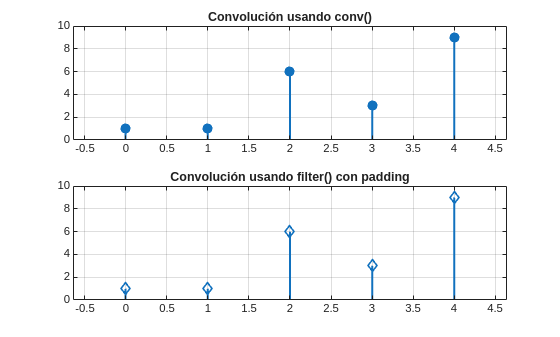


% Comparar resultados
n = 0:L_total-1;

figure;
subplot(2,1,1);
stem(n, x_conv, 'filled', 'LineWidth', 1.5);
title('Convolución usando conv()');
grid on;

subplot(2,1,2);
stem(n, x_filter, 'd', 'LineWidth', 1.5);
title('Convolución usando filter() con padding');
grid on;


% Verificación lógica
if isequal(x_conv, x_filter)
    disp('Verificación exitosa: Los métodos coinciden.');
else
    disp('Error: Los métodos no coinciden. Revisar el padding.');
end

Verificación exitosa: Los métodos coinciden.


## Ejercicio 3

Encontrar el ROC de:

    
$$x[n] = [0.5]^{n} u[n] + [0.3]^{n} u[n] + [0.9]^{n} u[n]$$


Analizando por separado, tenemos:


$$Z \Big\{ \left[ 0.5 \right] ^{n}u[n] \Big\} = \frac{1}{1-0.5z^{-1}}   \; , \qquad 0.5  < |z| $$



$$Z \Big\{ \left[ 0.3 \right] ^{n}u[n] \Big\} = \frac{1}{1-0.3z^{-1}}   \; , \qquad 0.3  < |z| $$



$$Z \Big\{ \left[ 0.9 \right] ^{n}u[n] \Big\} = \frac{1}{1-0.9z^{-1}}   \; , \qquad 0.9  < |z| $$


El ROC de $x[n]$ sera: $ROC: 0.9 < |z|$.

Luego, por propiedades de transformada Z:


$$Z \Big\{ ax[n] + by[n] \Big\} = a Z \Big\{ x[n] \Big\} + b Z \Big\{ y[n] \Big\} $$



$$Z \Big\{ x[n] \Big\} =   \frac{1}{1-0.5z^{-1}} +  \frac{1}{1-0.3z^{-1}}  +  \frac{1}{1-0.9z^{-1}}  $$


## Ejercicio 4

Considerando la ecuacion en diferencias:

    
$$y[n] - 0.7 y[n-1]   = x[n]$$


- La funcion de transferencia del sistema sera:


$$\begin{array}{rl}
y[n] - 0.7 y[n-1]  & = \delta[n] \\
Z \Big\{ y[n] - 0.7 y[n-1] \Big\}  & = Z \Big\{ \delta[n] \Big\}  \\
Y(z) - 0.7z^{-1}Y(z)  & =  1 \\
\left( 1-0.7z^{-1} \right) Y(z)  & = 1 \\
Y(z)  & = \frac{1}{\left( 1-0.7z^{-1} \right)} \\
H(z) & = \frac{1}{\left( 1-0.7z^{-1} \right)}
\end{array}$$


- Para $x[n] = \delta[n]$


$$Y(z) = H(z) = \frac{1}{\left( 1-0.7z^{-1} \right)}$$


- Para $x[n] = u[n]$


$$\begin{array}{rl}
Y(z) & = X(z) H(z) = \frac{1}{1-z^{-1}} \cdot \frac{1}{\left( 1-0.7z^{-1} \right)} \\
& = \frac{1}{1-1.7z^{-1}+0.7z^{-2}}
\end{array}$$


## Ejercicio 5

Considerando el sistema:


$$\left\{ \begin{array}{ll}
y[n]  & - 0.5 y[n-1] - 0.1 y[n-2] - 0.2 y[n-3]   = x[n] \\
x[n]  & = u[n] \\
y[-1]  & = 1 \\
y[-2]  & = 2 \\
y[-3]  & = 3
\end{array}
\right.$$


El sistema es inestable, con $ROC: 1 < |z|$.

La funcion de transferencia sera:


$$y[n] - 0.5 y[n-1] - 0.1 y[n-2] - 0.2 y[n-3]  = \delta[n]  \\
 \\
Z \Big\{ y[n] - 0.5 y[n-1] - 0.1 y[n-2] - 0.2 y[n-3] \Big\}  = Z \Big\{ \delta[n] \Big\}  \\
 \\
Y(z) - 0.5z^{-1}Y(z) - 0.1z^{-2}Y(z) - 0.2z^{-3}Y(z)  =  1 \\
 \\
\left( 1-0.5z^{-1}-0.1z^{-2}-0.2z^{-3} \right) Y(z)  = 1 \\
 \\
Y(z)  = \frac{1}{\left( 1-0.5z^{-1}-0.1z^{-2}-0.2z^{-3} \right)} \\
 \\
H(z) = \frac{1}{\left( 1-0.5z^{-1}-0.1z^{-2}-0.2z^{-3} \right)}
$$


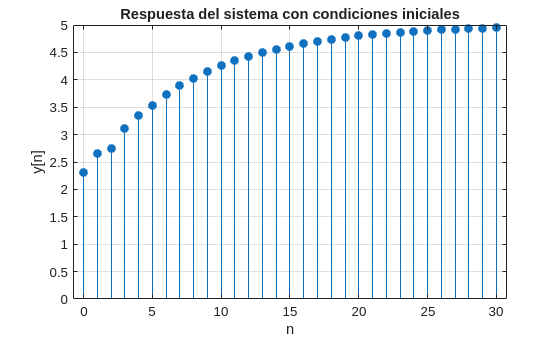

% 1. Definir coeficientes
a = [1, -0.5, -0.1, -0.2];    % den
b = [1];                      % num

% 2. Condiciones iniciales en orden [y[-1], y[-2], y[-3]...]
y_ic = [1, 2, 3]; 
x_ic = [0, 0, 0]; 

% 3. Usar funcion filtic
zi = filtic(b, a, y_ic, x_ic);

% 4. Definir el vector de tiempo y la entrada
n = 0:30;
x_conv = ones(size(n)); % u[n]

% 5. Calcular la respuesta
y = filter(b, a, x_conv, zi);

% 6. Graficar
stem(n, y, 'filled');
grid on;
xlabel('n'); ylabel('y[n]');
title('Respuesta del sistema con condiciones iniciales');